# SPM运动学模型

## 移动平台的描述方法——方位角-倾斜-扭转

syms phi theta sigma
% 先绕z轴转phi,再绕自身y轴转theta，再绕自身z轴转(sigma-phi)
Q=rotz(phi)*roty(theta)*rotz(sigma-phi)

$$Q = \left(\begin{array}{ccc} \sin\left(\varphi -\sigma \right)\,\sin\left(\varphi \right)+\cos\left(\varphi -\sigma \right)\,\cos\left(\varphi \right)\,\cos\left(\theta \right) & \sin\left(\varphi -\sigma \right)\,\cos\left(\varphi \right)\,\cos\left(\theta \right)-\cos\left(\varphi -\sigma \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\sin\left(\theta \right)\\ \cos\left(\varphi -\sigma \right)\,\cos\left(\theta \right)\,\sin\left(\varphi \right)-\sin\left(\varphi -\sigma \right)\,\cos\left(\varphi \right) & \cos\left(\varphi -\sigma \right)\,\cos\left(\varphi \right)+\sin\left(\varphi -\sigma \right)\,\cos\left(\theta \right)\,\sin\left(\varphi \right) & \sin\left(\varphi \right)\,\sin\left(\theta \right)\\ -\cos\left(\varphi -\sigma \right)\,\sin\left(\theta \right) & -\sin\left(\varphi -\sigma \right)\,\sin\left(\theta \right) & \cos\left(\theta \right) \end{array}\right)$$

Q=simplify(Q)

$$Q = \left(\begin{array}{ccc} \sin\left(\varphi -\sigma \right)\,\sin\left(\varphi \right)+\cos\left(\varphi -\sigma \right)\,\cos\left(\varphi \right)\,\cos\left(\theta \right) & \sin\left(\varphi -\sigma \right)\,\cos\left(\varphi \right)\,\cos\left(\theta \right)-\cos\left(\varphi -\sigma \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\sin\left(\theta \right)\\ \cos\left(\varphi -\sigma \right)\,\cos\left(\theta \right)\,\sin\left(\varphi \right)-\sin\left(\varphi -\sigma \right)\,\cos\left(\varphi \right) & \cos\left(\varphi -\sigma \right)\,\cos\left(\varphi \right)+\sin\left(\varphi -\sigma \right)\,\cos\left(\theta \right)\,\sin\left(\varphi \right) & \sin\left(\varphi \right)\,\sin\left(\theta \right)\\ -\cos\left(\varphi -\sigma \right)\,\sin\left(\theta \right) & -\sin\left(\varphi -\sigma \right)\,\sin\left(\theta \right) & \cos\left(\theta \right) \end{array}\right)$$

## u向量

% % u_i：先绕z轴转(pi/2+eta),再绕自身y轴转(pi-gamma)
% % 再绕自身z轴转(theta_i-(pi/2+eta))
% % eta_i=(i-1)*2/3*pi,i=1,2,3
% syms eta_i theta_i gamma
% Q_u=rotz(pi/2+eta_i)*roty(pi-gamma)*rotz(theta_i-(pi/2+eta_i));
% u_0=[0 0 1].';
% u_i=Q_u*u_0;
% simplify(u_i)

## u向量简化求法

% u_i：先绕z轴转(pi/2+eta_i),再绕自身y轴转(pi-gamma)
% 再绕自身z轴转(pi/2)，到达基座旋转关节初始位置
% eta_i=(i-1)*2/3*pi,i=1,2,3
% clear
syms eta_i gamma
Q_u=rotz(pi/2+eta_i)*roty(pi-gamma)*floor(rotz(pi/2))

$$Q\_u = \left(\begin{array}{ccc} -\sin\left(\eta_{i}+\frac{\pi }{2}\right) & \cos\left(\gamma \right)\,\cos\left(\eta_{i}+\frac{\pi }{2}\right) & \cos\left(\eta_{i}+\frac{\pi }{2}\right)\,\sin\left(\gamma \right)\\ \cos\left(\eta_{i}+\frac{\pi }{2}\right) & \cos\left(\gamma \right)\,\sin\left(\eta_{i}+\frac{\pi }{2}\right) & \sin\left(\gamma \right)\,\sin\left(\eta_{i}+\frac{\pi }{2}\right)\\ 0 & \sin\left(\gamma \right) & -\cos\left(\gamma \right) \end{array}\right)$$

u_0=[0 0 1].';
u_i=Q_u*u_0;
u_i=simplify(u_i)

$$u\_i = \left(\begin{array}{c} -\sin\left(\eta_{i}\right)\,\sin\left(\gamma \right)\\ \cos\left(\eta_{i}\right)\,\sin\left(\gamma \right)\\ -\cos\left(\gamma \right) \end{array}\right)$$

## v向量：中间旋转接头

% 基座旋转初始关节u_i绕自身z轴旋转theta_i,再绕y轴旋转结构参数alpha_1,从而得到v_i
% v_i:u_i绕基座关节坐标系z轴旋转theta_i,再绕自身坐标系y轴转alpha_1
syms alpha_1 theta_i
% Q_v=Q_u*rotz(theta_i+pi/2)*roty(alpha_1);%为什么要加一个pi/2？？？
Q_v=Q_u*rotz(theta_i)*roty(alpha_1);
simplify(Q_v)

$$ans = \left(\begin{array}{ccc} \sin\left(\alpha_{1}\right)\,\sin\left(\eta_{i}\right)\,\sin\left(\gamma \right)-\cos\left(\alpha_{1}\right)\,\cos\left(\eta_{i}\right)\,\cos\left(\theta_{i}\right)-\cos\left(\alpha_{1}\right)\,\cos\left(\gamma \right)\,\sin\left(\eta_{i}\right)\,\sin\left(\theta_{i}\right) & \cos\left(\eta_{i}\right)\,\sin\left(\theta_{i}\right)-\cos\left(\gamma \right)\,\cos\left(\theta_{i}\right)\,\sin\left(\eta_{i}\right) & -\cos\left(\eta_{i}\right)\,\sin\left(\alpha_{1}\right)\,\cos\left(\theta_{i}\right)-\cos\left(\alpha_{1}\right)\,\sin\left(\eta_{i}\right)\,\sin\left(\gamma \right)-\cos\left(\gamma \right)\,\sin\left(\alpha_{1}\right)\,\sin\left(\eta_{i}\right)\,\sin\left(\theta_{i}\right)\\ \cos\left(\alpha_{1}\right)\,\cos\left(\eta_{i}\right)\,\cos\left(\gamma \right)\,\sin\left(\theta_{i}\right)-\cos\left(\eta_{i}\right)\,\sin\left(\alpha_{1}\right)\,\sin\left(\gamma \right)-\cos\left(\alpha_{1}\right)\,\cos\left(\theta_{i}\right)\,\sin\left(\eta_{i}\right) & \sin\left(\eta_{i}\right)\,\sin\left(\theta_{i}\right)+\cos\left(\eta_{i}\right)\,\cos\left(\gamma \right)\,\cos\left(\theta_{i}\right) & \cos\left(\alpha_{1}\right)\,\cos\left(\eta_{i}\right)\,\sin\left(\gamma \right)-\sin\left(\alpha_{1}\right)\,\cos\left(\theta_{i}\right)\,\sin\left(\eta_{i}\right)+\cos\left(\eta_{i}\right)\,\cos\left(\gamma \right)\,\sin\left(\alpha_{1}\right)\,\sin\left(\theta_{i}\right)\\ \cos\left(\gamma \right)\,\sin\left(\alpha_{1}\right)+\cos\left(\alpha_{1}\right)\,\sin\left(\gamma \right)\,\sin\left(\theta_{i}\right) & \cos\left(\theta_{i}\right)\,\sin\left(\gamma \right) & \sin\left(\alpha_{1}\right)\,\sin\left(\gamma \right)\,\sin\left(\theta_{i}\right)-\cos\left(\alpha_{1}\right)\,\cos\left(\gamma \right) \end{array}\right)$$

v_0=[0 0 1].';
v_i=Q_v*v_0;
v_i=simplify(v_i)

$$v\_i = \left(\begin{array}{c} -\cos\left(\eta_{i}\right)\,\sin\left(\alpha_{1}\right)\,\cos\left(\theta_{i}\right)-\cos\left(\alpha_{1}\right)\,\sin\left(\eta_{i}\right)\,\sin\left(\gamma \right)-\cos\left(\gamma \right)\,\sin\left(\alpha_{1}\right)\,\sin\left(\eta_{i}\right)\,\sin\left(\theta_{i}\right)\\ \cos\left(\alpha_{1}\right)\,\cos\left(\eta_{i}\right)\,\sin\left(\gamma \right)-\sin\left(\alpha_{1}\right)\,\cos\left(\theta_{i}\right)\,\sin\left(\eta_{i}\right)+\cos\left(\eta_{i}\right)\,\cos\left(\gamma \right)\,\sin\left(\alpha_{1}\right)\,\sin\left(\theta_{i}\right)\\ \sin\left(\alpha_{1}\right)\,\sin\left(\gamma \right)\,\sin\left(\theta_{i}\right)-\cos\left(\alpha_{1}\right)\,\cos\left(\gamma \right) \end{array}\right)$$

## w向量

% 当移动平台MP到达初始位置时，
% w_i：先绕z轴转(pi/2+eta_i),再绕自身y轴转beta
% 再绕自身z轴转(-pi/2)，到达基座旋转关节初始位置
% eta_i=(i-1)*2/3*pi,i=1,2,3
syms eta_i beta
Q_w=rotz(pi/2+eta_i)*roty(beta)*floor(rotz(-pi/2))

$$Q\_w = \left(\begin{array}{ccc} \sin\left(\eta_{i}+\frac{\pi }{2}\right) & \cos\left(\beta \right)\,\cos\left(\eta_{i}+\frac{\pi }{2}\right) & \sin\left(\beta \right)\,\cos\left(\eta_{i}+\frac{\pi }{2}\right)\\ -\cos\left(\eta_{i}+\frac{\pi }{2}\right) & \cos\left(\beta \right)\,\sin\left(\eta_{i}+\frac{\pi }{2}\right) & \sin\left(\beta \right)\,\sin\left(\eta_{i}+\frac{\pi }{2}\right)\\ 0 & -\sin\left(\beta \right) & \cos\left(\beta \right) \end{array}\right)$$

w_0=[0 0 1].';
w_i_=Q_w*w_0;
w_i_=simplify(w_i_)

$$w\_i\_ = \left(\begin{array}{c} -\sin\left(\beta \right)\,\sin\left(\eta_{i}\right)\\ \cos\left(\eta_{i}\right)\,\sin\left(\beta \right)\\ \cos\left(\beta \right) \end{array}\right)$$

%% w_i:v_i绕基座关节坐标系z轴旋转psi_i,再绕自身坐标系y轴转alpha_2
syms alpha_2 psi_i
Q_w=Q_v*rotz(psi_i)*roty(alpha_2);
simplify(Q_w)

w_0=[0 0 1].';
w_i=Q_w*w_0;
w_i=simplify(w_i)

## 动平台的w

syms eta_i beta phi_1 phi_2 phi_3
Q=rotz(phi_1)*roty(phi_2)*rotz(phi_3)

$$Q = \left(\begin{array}{ccc} \cos\left(\varphi_{1}\right)\,\cos\left(\varphi_{2}\right)\,\cos\left(\varphi_{3}\right)-\sin\left(\varphi_{1}\right)\,\sin\left(\varphi_{3}\right) & -\cos\left(\varphi_{3}\right)\,\sin\left(\varphi_{1}\right)-\cos\left(\varphi_{1}\right)\,\cos\left(\varphi_{2}\right)\,\sin\left(\varphi_{3}\right) & \cos\left(\varphi_{1}\right)\,\sin\left(\varphi_{2}\right)\\ \cos\left(\varphi_{1}\right)\,\sin\left(\varphi_{3}\right)+\cos\left(\varphi_{2}\right)\,\cos\left(\varphi_{3}\right)\,\sin\left(\varphi_{1}\right) & \cos\left(\varphi_{1}\right)\,\cos\left(\varphi_{3}\right)-\cos\left(\varphi_{2}\right)\,\sin\left(\varphi_{1}\right)\,\sin\left(\varphi_{3}\right) & \sin\left(\varphi_{1}\right)\,\sin\left(\varphi_{2}\right)\\ -\cos\left(\varphi_{3}\right)\,\sin\left(\varphi_{2}\right) & \sin\left(\varphi_{2}\right)\,\sin\left(\varphi_{3}\right) & \cos\left(\varphi_{2}\right) \end{array}\right)$$

Q_w=Q*rotz(pi/2+eta_i)*roty(beta)*floor(rotz(-pi/2));
Q_w=simplify(Q_w)

w_0=[0 0 1].';
w_i=Q_w*w_0;
w_i=simplify(w_i)

$$w\_i = \left(\begin{array}{c} \cos\left(\beta \right)\,\cos\left(\varphi_{1}\right)\,\sin\left(\varphi_{2}\right)-\sin\left(\beta \right)\,\left(\cos\left(\eta_{i}+\frac{\pi }{2}\right)\,\left(\sin\left(\varphi_{1}\right)\,\sin\left(\varphi_{3}\right)-\cos\left(\varphi_{1}\right)\,\cos\left(\varphi_{2}\right)\,\cos\left(\varphi_{3}\right)\right)+\sin\left(\eta_{i}+\frac{\pi }{2}\right)\,\left(\cos\left(\varphi_{3}\right)\,\sin\left(\varphi_{1}\right)+\cos\left(\varphi_{1}\right)\,\cos\left(\varphi_{2}\right)\,\sin\left(\varphi_{3}\right)\right)\right)\\ \sin\left(\beta \right)\,\left(\cos\left(\eta_{i}\right)\,\left(\cos\left(\varphi_{1}\right)\,\cos\left(\varphi_{3}\right)-\cos\left(\varphi_{2}\right)\,\sin\left(\varphi_{1}\right)\,\sin\left(\varphi_{3}\right)\right)-\sin\left(\eta_{i}\right)\,\left(\cos\left(\varphi_{1}\right)\,\sin\left(\varphi_{3}\right)+\cos\left(\varphi_{2}\right)\,\cos\left(\varphi_{3}\right)\,\sin\left(\varphi_{1}\right)\right)\right)+\cos\left(\beta \right)\,\sin\left(\varphi_{1}\right)\,\sin\left(\varphi_{2}\right)\\ \cos\left(\beta \right)\,\cos\left(\varphi_{2}\right)+\cos\left(\eta_{i}\right)\,\sin\left(\beta \right)\,\sin\left(\varphi_{2}\right)\,\sin\left(\varphi_{3}\right)+\cos\left(\varphi_{3}\right)\,\sin\left(\beta \right)\,\sin\left(\eta_{i}\right)\,\sin\left(\varphi_{2}\right) \end{array}\right)$$

## 形成闭环

syms w_ix w_iy w_iz
w_i=[w_ix w_iy w_iz].'
COSalpha2=v_i.'*w_i;
simplify(COSalpha2)
collect(COSalpha2)

## 初始位置动画

eta_i=0;%2*pi/3;
gamma=60/180*pi;
beta=45/180*pi;
alpha_1=pi/2;
alpha_2=pi/2;
% gamma=pi/3;
Q_u=rotz(pi/2+eta_i)*roty(pi-gamma)*floor(rotz(pi/2));
u_0=[0 0 1].';
u_i=Q_u*u_0;
Q_0=rotx(0);
view([6,2,2]);
tranimate(Q_0,Q_u)
hold on
plot3(u_i(1),u_i(2),u_i(3),'ro','MarkerFaceColor','r')

% alpha_1=pi/2;
theta_i=0;%pi/6;
Q_v=Q_u*rotz(theta_i)*roty(alpha_1);
v_0=[0 0 1].';
v_i=Q_v*v_0;
tranimate(Q_u,Q_v)
plot3(v_i(1),v_i(2),v_i(3),'go','MarkerFaceColor','g')

psi_i=1.8326;%1.7453;%pi/3*2;     0;%
% alpha_2=pi*5/8
Q_w=Q_v*rotz(psi_i)*roty(alpha_2);
w_0=[0 0 1].';
w_i=Q_w*w_0;
tranimate(Q_v,Q_w)
plot3(w_i(1),w_i(2),w_i(3),'bo','MarkerFaceColor','b')
% beta=pi*1/4

Q=rotz(0)*roty(0)*rotz(0);
Q_w_=Q*rotz(pi/2+eta_i)*roty(beta)*floor(rotz(-pi/2))

Q_w_ =     1.0000    0.0000    0.0000
   -0.0000    0.7071    0.7071
         0   -0.7071    0.7071


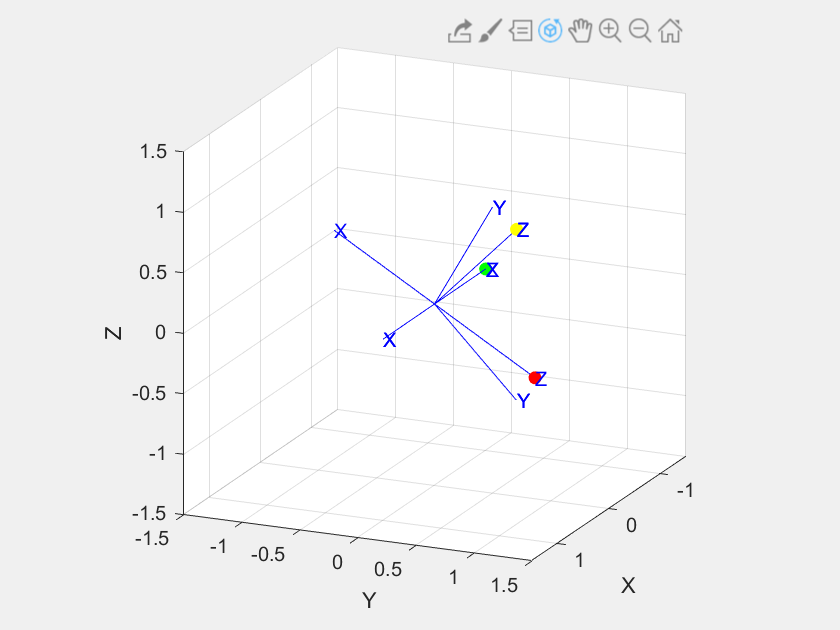

w_0=[0 0 1].';
w_i_=Q_w_*w_0;
tranimate(Q_0,Q_w_)
plot3(w_i_(1),w_i_(2),w_i_(3),'yo','MarkerFaceColor','y')

## 正解

% 已知theta=[theta_1 theta_2 theta3],主动关节输入角
% 求动平台zyz欧拉角phi=[phi_1 phi_2 phi_3]
syms eta_i gamma alpha_1 theta_i phi_1 phi_2 phi_3 beta
Q_u=rotz(pi/2+eta_i)*roty(pi-gamma)*floor(rotz(pi/2));
Q_u=simplify(Q_u);
u_0=[0 0 1].';
u_i=Q_u*u_0;
u_i=simplify(u_i);
Q_v=Q_u*rotz(theta_i)*roty(alpha_1);
Q_v=simplify(Q_v);
v_0=[0 0 1].';
v_i=Q_v*v_0;
v_i=simplify(v_i);
Q=rotz(phi_1)*roty(phi_2)*rotz(phi_3);
w_0=[0 0 1].';
Q_w=Q*rotz(pi/2+eta_i)*roty(beta)*floor(rotz(-pi/2));
w_i=Q_w*w_0;
w_i=simplify(w_i);
COSalpha2=v_i.'*w_i;
simplify(COSalpha2)

collect(COSalpha2)

uv=cross(v_i,u_i);
vw=cross(w_i,v_i);
psi_i=acos(dot(uv,vw)/(norm(uv)*norm(vw)))

% w_i:v_i绕基座关节坐标系z轴旋转psi_i,再绕自身坐标系y轴转alpha_2
syms alpha_2
Q_w=Q_v*rotz(psi_i)*roty(alpha_2);
%Q_w=simplify(Q_w)
w_0=[0 0 1].';
w_i=Q_w*w_0;
simplify(w_i)

## 1.运动学雅克比矩阵

% % 例子：角速度为[0 0 1].'
% syms theta
% w=[0 0 1].';
% p=[cos(theta) sin(theta) 0].';
% v=cross(w,p)
% % 叉乘,混合积
% syms a b c d e f g h i
% A=[a b c]
% B=[d e f]
% C=[g h i]
% cross(A,B)

% 雅克比矩阵
a_i=cross(v_i.',w_i.')

b_i=cross(u_i,v_i).'*w_i

j_i=a_i./b_i;
simplify(j_i.')

$$ans = \begin{array}{l} \left(\begin{array}{c} \frac{\cos\left(\eta_{i}\right)\,\cos\left(\psi_{i}\right)\,\sin\left(\theta_{i}\right)+\cos\left(\alpha_{1}\right)\,\cos\left(\eta_{i}\right)\,\cos\left(\theta_{i}\right)\,\sin\left(\psi_{i}\right)-\cos\left(\gamma \right)\,\cos\left(\psi_{i}\right)\,\cos\left(\theta_{i}\right)\,\sin\left(\eta_{i}\right)-\sin\left(\alpha_{1}\right)\,\sin\left(\eta_{i}\right)\,\sin\left(\gamma \right)\,\sin\left(\psi_{i}\right)+\cos\left(\alpha_{1}\right)\,\cos\left(\gamma \right)\,\sin\left(\eta_{i}\right)\,\sin\left(\psi_{i}\right)\,\sin\left(\theta_{i}\right)}{\sigma_{1}}\\ \frac{\cos\left(\psi_{i}\right)\,\sin\left(\eta_{i}\right)\,\sin\left(\theta_{i}\right)+\cos\left(\eta_{i}\right)\,\cos\left(\gamma \right)\,\cos\left(\psi_{i}\right)\,\cos\left(\theta_{i}\right)+\cos\left(\alpha_{1}\right)\,\cos\left(\theta_{i}\right)\,\sin\left(\eta_{i}\right)\,\sin\left(\psi_{i}\right)+\cos\left(\eta_{i}\right)\,\sin\left(\alpha_{1}\right)\,\sin\left(\gamma \right)\,\sin\left(\psi_{i}\right)-\cos\left(\alpha_{1}\right)\,\cos\left(\eta_{i}\right)\,\cos\left(\gamma \right)\,\sin\left(\psi_{i}\right)\,\sin\left(\theta_{i}\right)}{\sigma_{1}}\\ -\frac{\cos\left(\gamma \right)\,\sin\left(\alpha_{1}\right)\,\sin\left(\psi_{i}\right)-\cos\left(\psi_{i}\right)\,\cos\left(\theta_{i}\right)\,\sin\left(\gamma \right)+\cos\left(\alpha_{1}\right)\,\sin\left(\gamma \right)\,\sin\left(\psi_{i}\right)\,\sin\left(\theta_{i}\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\alpha_{1}\right)\,\sin\left(\psi_{i}\right) \end{array}$$

syms a_11 a_12 a_13
syms a_21 a_22 a_23
syms a_31 a_32 a_33
syms b_1 b_2 b_3
A=[ a_11 a_12 a_13
 a_21 a_22 a_23
 a_31 a_32 a_33].';
B=diag([b_1 b_2 b_3]);
J=inv(B)*A

$$J = \left(\begin{array}{ccc} \frac{a_{11}}{b_{1}} & \frac{a_{21}}{b_{1}} & \frac{a_{31}}{b_{1}}\\ \frac{a_{12}}{b_{2}} & \frac{a_{22}}{b_{2}} & \frac{a_{32}}{b_{2}}\\ \frac{a_{13}}{b_{3}} & \frac{a_{23}}{b_{3}} & \frac{a_{33}}{b_{3}} \end{array}\right)$$

## 2.逆运动学模型

p_0=[0 0 1].';
p=Q*p_0

$$p = \left(\begin{array}{c} \cos\left(\varphi \right)\,\sin\left(\theta \right)\\ \sin\left(\varphi \right)\,\sin\left(\theta \right)\\ \cos\left(\theta \right) \end{array}\right)$$

syms d_phi d_theta d_sigma
dp=diff(p,'phi')*d_phi+diff(p,'theta')*d_theta

$$dp = \left(\begin{array}{c} d_{\theta }\,\cos\left(\varphi \right)\,\cos\left(\theta \right)-d_{\varphi }\,\sin\left(\varphi \right)\,\sin\left(\theta \right)\\ d_{\varphi }\,\cos\left(\varphi \right)\,\sin\left(\theta \right)+d_{\theta }\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\\ -d_{\theta }\,\sin\left(\theta \right) \end{array}\right)$$

% syms x y z
% r=[x,y,z].';
% skew(r)
% omega=-inv(skew(p))*diff(p)
% syms omega_x omega_y omega_z
% omega=[omega_x omega_y omega_z].';
% cross(omega,p)
dQ=diff(Q,'phi')*d_phi+diff(Q,'theta')*d_theta+diff(Q,'sigma')*d_sigma

omega_s=dQ*(Q.')

omega_s=simplify(omega_s)

$$omega\_s = \begin{array}{l} \left(\begin{array}{ccc} 0 & d_{\varphi }\,\cos\left(\theta \right)-d_{\varphi }-d_{\sigma }\,\cos\left(\theta \right) & d_{\theta }\,\cos\left(\varphi \right)-\sigma_{2}+\sigma_{1}\\ d_{\varphi }-d_{\varphi }\,\cos\left(\theta \right)+d_{\sigma }\,\cos\left(\theta \right) & 0 & d_{\theta }\,\sin\left(\varphi \right)+\sigma_{4}-\sigma_{3}\\ \sigma_{2}-d_{\theta }\,\cos\left(\varphi \right)-\sigma_{1} & \sigma_{3}-\sigma_{4}-d_{\theta }\,\sin\left(\varphi \right) & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=d_{\sigma }\,\sin\left(\varphi \right)\,\sin\left(\theta \right)\\ \sigma_{2}=d_{\varphi }\,\sin\left(\varphi \right)\,\sin\left(\theta \right)\\ \sigma_{3}=d_{\sigma }\,\cos\left(\varphi \right)\,\sin\left(\theta \right)\\ \sigma_{4}=d_{\varphi }\,\cos\left(\varphi \right)\,\sin\left(\theta \right) \end{array}$$

omega_x=omega_s(3,2)

$$omega\_x = d_{\sigma }\,\cos\left(\varphi \right)\,\sin\left(\theta \right)-d_{\varphi }\,\cos\left(\varphi \right)\,\sin\left(\theta \right)-d_{\theta }\,\sin\left(\varphi \right)$$

omega_y=omega_s(1,3)

$$omega\_y = d_{\theta }\,\cos\left(\varphi \right)-d_{\varphi }\,\sin\left(\varphi \right)\,\sin\left(\theta \right)+d_{\sigma }\,\sin\left(\varphi \right)\,\sin\left(\theta \right)$$

omega_z=omega_s(2,1)

$$omega\_z = d_{\varphi }-d_{\varphi }\,\cos\left(\theta \right)+d_{\sigma }\,\cos\left(\theta \right)$$

## 输入关节为theta1、theta2、theta3的指数积反解

% w_i0=[-sin(beta)*sin(eta_i); cos(eta_i)*sin(beta); cos(beta)];
syms w_ix w_iy w_iz u_i0x u_i0y u_i0z v_i0x v_i0y v_i0z theta_i
w_ithe=[w_ix w_iy w_iz].';
u_i0=[u_i0x u_i0y u_i0z].';
v_i0=[v_i0x v_i0y v_i0z].';
v_ithe=expprod(u_i0,theta_i)*v_i0;
COSalpha2=v_ithe.'*w_ithe

$$COSalpha2 = \begin{array}{l} w_{\mathrm{ix}}\,\left(v_{\mathrm{i0z}}\,\left(u_{\mathrm{i0y}}\,\sin\left(\theta_{i}\right)-\sigma_{2}\right)-v_{\mathrm{i0y}}\,\left(u_{\mathrm{i0z}}\,\sin\left(\theta_{i}\right)+\sigma_{3}\right)+v_{\mathrm{i0x}}\,\left(\left({u_{\mathrm{i0y}}}^{2}+{u_{\mathrm{i0z}}}^{2}\right)\,\left(\cos\left(\theta_{i}\right)-1\right)+1\right)\right)+w_{\mathrm{iy}}\,\left(v_{\mathrm{i0x}}\,\left(u_{\mathrm{i0z}}\,\sin\left(\theta_{i}\right)-\sigma_{3}\right)-v_{\mathrm{i0z}}\,\left(u_{\mathrm{i0x}}\,\sin\left(\theta_{i}\right)+\sigma_{1}\right)+v_{\mathrm{i0y}}\,\left(\left({u_{\mathrm{i0x}}}^{2}+{u_{\mathrm{i0z}}}^{2}\right)\,\left(\cos\left(\theta_{i}\right)-1\right)+1\right)\right)+w_{\mathrm{iz}}\,\left(v_{\mathrm{i0y}}\,\left(u_{\mathrm{i0x}}\,\sin\left(\theta_{i}\right)-\sigma_{1}\right)-v_{\mathrm{i0x}}\,\left(u_{\mathrm{i0y}}\,\sin\left(\theta_{i}\right)+\sigma_{2}\right)+v_{\mathrm{i0z}}\,\left(\left({u_{\mathrm{i0x}}}^{2}+{u_{\mathrm{i0y}}}^{2}\right)\,\left(\cos\left(\theta_{i}\right)-1\right)+1\right)\right)\\ \mathrm{where}\\ \sigma_{1}=u_{\mathrm{i0y}}\,u_{\mathrm{i0z}}\,\left(\cos\left(\theta_{i}\right)-1\right)\\ \sigma_{2}=u_{\mathrm{i0x}}\,u_{\mathrm{i0z}}\,\left(\cos\left(\theta_{i}\right)-1\right)\\ \sigma_{3}=u_{\mathrm{i0x}}\,u_{\mathrm{i0y}}\,\left(\cos\left(\theta_{i}\right)-1\right) \end{array}$$

syms v_i0x v_i0y v_i0z psi_i
v_i0=[v_i0x v_i0y v_i0z].';
exp=expprod(v_i0,psi_i)

$$exp = \begin{array}{l} \left(\begin{array}{ccc} \left({v_{\mathrm{i0y}}}^{2}+{v_{\mathrm{i0z}}}^{2}\right)\,\left(\cos\left(\psi_{i}\right)-1\right)+1 & -v_{\mathrm{i0z}}\,\sin\left(\psi_{i}\right)-\sigma_{3} & v_{\mathrm{i0y}}\,\sin\left(\psi_{i}\right)-\sigma_{2}\\ v_{\mathrm{i0z}}\,\sin\left(\psi_{i}\right)-\sigma_{3} & \left({v_{\mathrm{i0x}}}^{2}+{v_{\mathrm{i0z}}}^{2}\right)\,\left(\cos\left(\psi_{i}\right)-1\right)+1 & -v_{\mathrm{i0x}}\,\sin\left(\psi_{i}\right)-\sigma_{1}\\ -v_{\mathrm{i0y}}\,\sin\left(\psi_{i}\right)-\sigma_{2} & v_{\mathrm{i0x}}\,\sin\left(\psi_{i}\right)-\sigma_{1} & \left({v_{\mathrm{i0x}}}^{2}+{v_{\mathrm{i0y}}}^{2}\right)\,\left(\cos\left(\psi_{i}\right)-1\right)+1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=v_{\mathrm{i0y}}\,v_{\mathrm{i0z}}\,\left(\cos\left(\psi_{i}\right)-1\right)\\ \sigma_{2}=v_{\mathrm{i0x}}\,v_{\mathrm{i0z}}\,\left(\cos\left(\psi_{i}\right)-1\right)\\ \sigma_{3}=v_{\mathrm{i0x}}\,v_{\mathrm{i0y}}\,\left(\cos\left(\psi_{i}\right)-1\right) \end{array}$$

## 雅克比矩阵

syms w_1x w_1y w_1z u_1x u_1y u_1z v_1x v_1y v_1z
w_1=[w_1x w_1y w_1z].';
u_1=[u_1x u_1y u_1z].';
v_1=[v_1x v_1y v_1z].';
syms w_2x w_2y w_2z u_2x u_2y u_2z v_2x v_2y v_2z
w_2=[w_2x w_2y w_2z].';
u_2=[u_2x u_2y u_2z].';
v_2=[v_2x v_2y v_2z].';
syms w_3x w_3y w_3z u_3x u_3y u_3z v_3x v_3y v_3z
w_3=[w_3x w_3y w_3z].';
u_3=[u_3x u_3y u_3z].';
v_3=[v_3x v_3y v_3z].';
Haq=[
    u_1 -u_2 0;
    0   -u_2 u_3;
];

Hpq=[
    v_1 w_1 -v_2 -w_2 0     0
    0   0   -v_2 -w_2 v_3   w_3
];

invHpq=inv(Hpq);

invHpq=simplify(inv(Hpq));
Gq=simplify(invHpq*Haq);
syms theta_1dot theta_2dot theta_3dot
q_adot=[theta_1dot theta_2dot theta_3dot].';
q_pdot=Gq*q_adot;
psi_1dot=q_pdot(1);
xi_1dot=q_pdot(2);
omega=[u_1 v_1 w_1]*[theta_1dot psi_1dot xi_1dot].'